% Procedures will be listed in order and hopefully executed
% in sections.
% Code written by Aswath Ashok for the Data Analysis module
% at Cranfield University for the MSc CFD course.
%

clear all; close all; clc;

%% READ CHANNEL PARAMETERS AND SPATIO-TEMPORAL AVERAGES

% read parameters
% Lz, Lx, Ly, nu, Delta p
params = xlsread('Reynolds_stresses.xlsx','parameters');

Lz = params(1); Lx = params(2); Ly = params(3);
nu = params(4); % kinematic viscosity

% these values are equal to unity because they are the reference quantities
% used to make the data dimensionless
u_b = 1.0; % bulk velocity (average velocity in the entire channel)
rho = 1.0; % density
delta = Lx/2; % boundary layer thickness  =  channel half-height

% bulk Reynolds number based on channel half height and mean velocity
Re_b  =  u_b*delta/nu;

% read wall-normal coordinate and spatio-temporal averages
% x, <w>, <w'w'>, <u'u'> , <v'v'>, <u'w'>
ST_ave_dat = xlsread('Reynolds_stresses.xlsx','Reynolds_stresses');


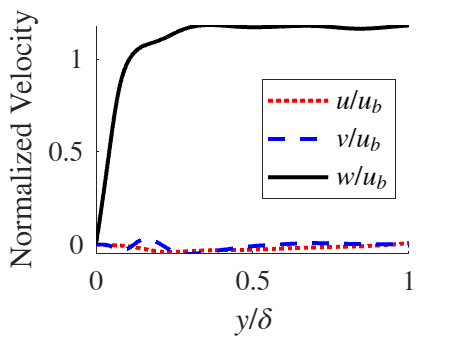


%% READ TIME SAMPLES AT PROBES PLACED ALONG A WALL_NORMAL LINE

hinfo  =  hdf5info('time_samples.hdf5');

% sampling time
t_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(1));
% wall-normal location of the samples
y_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(5))+1.0;

% sampled velocity components
% each row represents a time instant as dictated by t_smpl
% each column represents a spatial location as dictated by y_smpl
w_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(2));
u_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(3));
v_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(4));


%% instantaneous velocity plots
figure(1)
hold on
plot(y_smpl,u_smpl(1,:),':r',LineWidth=2)
plot(y_smpl,v_smpl(1,:),'--b',LineWidth=2)
plot(y_smpl,w_smpl(1,:),'-k',LineWidth=2)
xlabel('$y/\delta$','Interpreter','latex','FontSize',14)
ylabel('Normalized Velocity','Interpreter','latex','FontSize',14)
xlim([0,1])
legend('$u/u_b$','$v/u_b$','$w/u_b$',...
    'Interpreter','latex','FontSize',14,'Location','east')
set(gca,'TickLabelInterpreter','latex','FontSize',14)

% Upto here is from the provided assignment file.


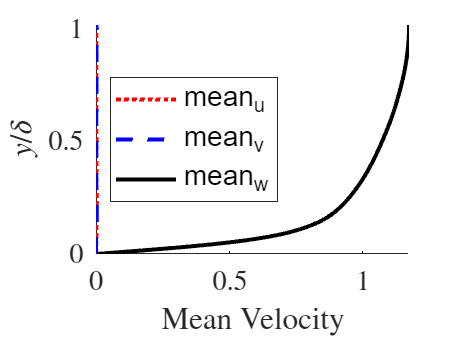


%% MEAN OF VELOCITY COMPONENTS FOR 126 Sampling points
mean_u = mean(u_smpl);
mean_v = mean(v_smpl);
mean_w = mean(w_smpl);

figure(2)
hold on
plot(mean_u,y_smpl,':r',LineWidth=2)
plot(mean_v,y_smpl,'--b',LineWidth=2)
plot(mean_w,y_smpl,'-k',LineWidth=2)
ylabel('$y/\delta$','Interpreter','latex','FontSize',14)
xlabel('Mean Velocity','Interpreter','latex','FontSize',14)
legend('mean_u','mean_v','mean_w',...
    'FontSize',14,'Location','west')
set(gca,'TickLabelInterpreter','latex','FontSize',14)

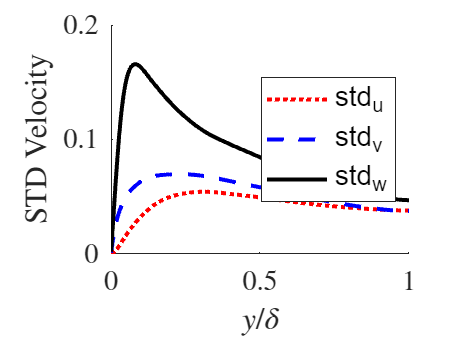



%% STANDARD DEVIATION OF THE VELOCITY COMPONENTS

std_u = std(u_smpl);
std_v = std(v_smpl);
std_w = std(w_smpl);

figure(3)
hold on
plot(y_smpl,std_u,':r',LineWidth=2)
plot(y_smpl,std_v,'--b',LineWidth=2)
plot(y_smpl,std_w,'-k',LineWidth=2)
xlabel('$y/\delta$','Interpreter','latex','FontSize',14)
ylabel('STD Velocity','Interpreter','latex','FontSize',14)
xlim([0,1])
legend('std_u','std_v','std_w',...
    'FontSize',14,'Location','east')
set(gca,'TickLabelInterpreter','latex','FontSize',14)


%% GRADIENT OF MEAN STREAMWISE VELOCITY COMPONENT.

grad_w = gradient(mean_w)

grad_w =     0.0115    0.0117    0.0121    0.0125    0.0129    0.0133    0.0137    0.0141    0.0145    0.0150    0.0154    0.0158    0.0163    0.0167    0.0171    0.0175    0.0178    0.0182    0.0185    0.0188    0.0190    0.0192    0.0194    0.0195    0.0196    0.0196    0.0196    0.0195    0.0193    0.0192    0.0189    0.0187    0.0184    0.0180    0.0177    0.0173    0.0168    0.0164    0.0159    0.0154    0.0149    0.0145    0.0140    0.0135    0.0130    0.0125    0.0121    0.0117    0.0112    0.0108


grad_u = gradient(mean_u)

grad_u = 1.0e-04 *

    0.0052    0.0081    0.0141    0.0207    0.0280    0.0358    0.0444    0.0538    0.0639    0.0749    0.0867    0.0993    0.1128    0.1272    0.1424    0.1585    0.1753    0.1928    0.2109    0.2295    0.2484    0.2674    0.2864    0.3052    0.3236    0.3412    0.3579    0.3734    0.3875    0.3999    0.4105    0.4191    0.4256    0.4300    0.4325    0.4333    0.4330    0.4324    0.4322    0.4337    0.4375    0.4441    0.4532    0.4634    0.4727    0.4787    0.4793    0.4734    0.4614    0.4452


grad_v = gradient(mean_v)

grad_v = 1.0e-03 *

   -0.0571   -0.0568   -0.0560   -0.0552   -0.0542   -0.0530   -0.0517   -0.0503   -0.0486   -0.0469   -0.0449   -0.0428   -0.0405   -0.0380   -0.0353   -0.0325   -0.0294   -0.0261   -0.0225   -0.0188   -0.0148   -0.0106   -0.0062   -0.0016    0.0032    0.0082    0.0134    0.0187    0.0241    0.0296    0.0351    0.0407    0.0464    0.0521    0.0580    0.0642    0.0708    0.0780    0.0860    0.0947    0.1042    0.1142    0.1240    0.1331    0.1407    0.1460    0.1485    0.1476    0.1434    0.1364


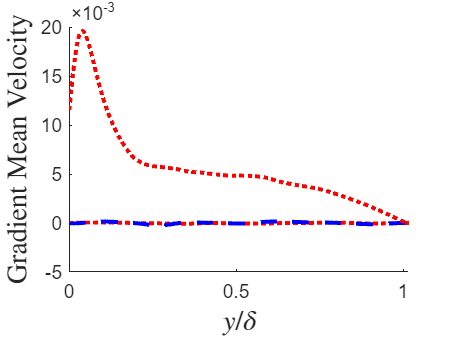


figure (4)
hold on
plot(y_smpl,grad_u,':r',LineWidth=2)
plot(y_smpl,grad_v,'--b',LineWidth=2)
plot(y_smpl,grad_w,':r',LineWidth=2)
xlabel('$y/\delta$','Interpreter','latex','FontSize',14)
ylabel('Gradient Mean Velocity','Interpreter','latex','FontSize',14)